clear all
%Assign parameters
SIR_num = [9900,100,0]';%population distribution
population = sum(SIR_num);
SIR_initial = SIR_num / population;

deltaT = 0.01;%time step
tTotal = 3650;%total modelling time

colorCode = ["#EDB120", "#FF0000", "#0000FF"];

%Vam
beta = 2*10^-6;%infection rate
sigma = 0;%revovery rate
mu = 0;%death due to disease
omega = 0;%loss of immunity
lambda = 0.011/365;%birth rate
ds = 1/(82.06*365);%natrual death
di = 0.1/365;%natural death
dr = 0.01/365;%natural death

%Predict using RK4
t(1) = 0; %start with 0 day
SIR_RK(:,1) = SIR_initial;
n = 1;

while t(n)<= tTotal
    SIR_RK(:,n+1) = SIR_RK4(deltaT,SIR_RK(:,n),lambda,beta,sigma,omega,mu,ds,di,dr);
    t(n+1) = t(n) + deltaT;
    n = n + 1;
end

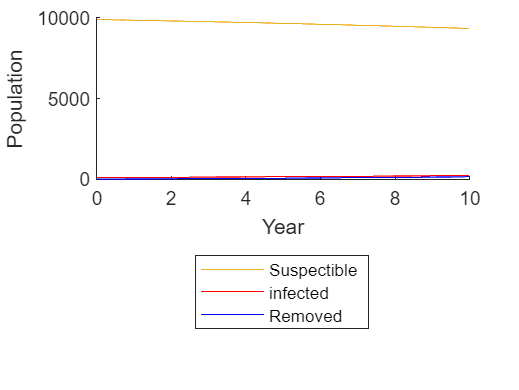

%Plot RK4
sizeSIR = size(SIR_RK);
numVar = sizeSIR(1);
legendName = ['Suspectible','infected','Removed'];
for i  = 1:numVar
    hold on
    plot(t/365,SIR_RK(i,:)*population,Color=colorCode(i))
end
xlabel('Year')
ylabel('Population')
hold off
legend('Suspectible','infected','Removed',Location='southoutside')